# Przetwarzanie danych w pakiecie MATLAB - projekt

#### Autor: Jakub Kozub, Informatyka i Ekonometria (stacjonarne), sem. 2

#### Dane: "Airline Passenger Satisfaction"

Źródło: [https://www.kaggle.com/datasets/teejmahal20/airline-passenger-satisfaction](https://www.kaggle.com/datasets/teejmahal20/airline-passenger-satisfaction)

## Przygotowanie danych do analizy

Dane pobrane w formie pliku csv zawierają informacje o pasażerach linii lotniczych, m. in. takie jak płeć, lojalność wobec linii, klasa czy długość lotu oraz oceny (w skali 0-5), jakie wystawili przewoźnikowi w kilkunastu kategoriach dotyczących różnych aspektów podróży, jak i ogólny werdykt wyrażający zadowolenie lub jego brak.

### Załadowanie danych

fname = 'train.csv';
%funkcja badajaca najlepsze opcje importu pliku
opts = detectImportOptions(fname);
%utworzenie tabeli na podstawie danych z pliku
pasazerowie = readtable(fname, opts);

%zmiana nazwy pierwszej kolumny, ktorej pierwotna nazwa byla problematyczna
%dla Matlaba i zostala zmieniona na 'Var1'
pasazerowie.Properties.VariableNames(1) = {'Number'};
%korekta nazwy ostatniej kolumny w celu zachowania spojnosci z pozostalymi
pasazerowie.Properties.VariableNames("satisfaction") = {'Satisfaction'};

### Uzupełnienie danych o dodatkowe kolumny

#### Wygenerowanie danych czasowych

W celu utworzenia kolumny z datami i godzinami startu lotów, które odbyli i oceniali poszczególni pasażerowie tworzymy wektor n kolejnych czasów o 5-minutowym interwale, które następnie losowo przydzielamy wszystkim pasażerom.

n = height(pasazerowie); %liczba wierszy tabeli
data1 = datetime(2022,1,1,6,0,0);
daty = data1+minutes(5:5:5*n);
%losowe przyporzadkowanie kazdemu wierszowi tabeli jednego z indeksow
%wektora dat poprzez utworzenie wektora nx1 zawierajacego liczby
%odpowiadajace indeksom wektora dat:
ind = randi(length(daty), n, 1); 
datKol = reshape(daty(ind), n, 1);
%dodanie kolumny do tabeli i przesuniecie jej
pasazerowie.DepartureTime = datKol;
pasazerowie = movevars(pasazerowie,"DepartureTime","Before","id");

#### Konwersja kolumny liczbowej na liczby w formie napisów

pasazerowie.id = string(pasazerowie.id);

### Analiza braków i wartości odstających

sum(ismissing(pasazerowie))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   310     0


sum(isoutlier(pasazerowie, 1, "DataVariables", vartype("numeric")))

ans =            0           0           0           0           0           0           0           0        7142           0           0           0           0           0           0           0           0           0           0           0           0           0           0       45236       45435           0


Dane posiadają 310 wartości brakujących w kolumnie 25 (opóźnienie przylotu) oraz kolejno 7142, 45236 i 45435 wartości odstających w kolumnach dotyczących dystansu lotu oraz opóźnień odlotu i przylotu. Warto jednak zauważyć, że ogromna liczba outlierów w kolumnach dotyczących opóźnień może wynikać z faktu, że duża część lotów odbywa się bez opóźnień, co powoduje trudności w analizie tych zmiennych, gdyż tworzą się dwie, dosyć odległe od siebie wartościami grupy - opóźnienia zerowe lub znikome oraz opóźnienia znaczące. Można przypuszczać, że któraś z tych grup została uznana za wartości odstające, wobec czego należy te kolumny tymczasowo zignorować lub sprawdzić z wykorzystaniem innej metody.

Liczba kolumn z brakami lub outlierami jest znikoma, więc w celu urozmaicenia procesu czyszczenia danych wygenerujemy w kolejnych krokach dodatkowe wartości brakujące i odstające.

sum(isoutlier(pasazerowie.DepartureDelayInMinutes, "percentiles",[1 99]))

ans = 1023

sum(isoutlier(pasazerowie.DepartureDelayInMinutes, "percentiles",[50 99]))

ans = 1023

sum(isoutlier(pasazerowie.ArrivalDelayInMinutes, "percentiles",[1 99]))

ans = 1020

sum(isoutlier(pasazerowie.ArrivalDelayInMinutes, "percentiles",[50 99]))

ans = 1020

#### Generacja braków

Ustalamy liczby braków i wstawiamy je do kilku istotnych kolumn różnych typów.

liczbaMV = [124, 28, 17, 54];
indMV1 = datasample(1:n, liczbaMV(1), 'Replace',false);
pasazerowie{indMV1,"Age"} = NaN;
indMV2 = datasample(1:n, liczbaMV(2), 'Replace',false);
pasazerowie{indMV2,"Gender"} = {''};
indMV3 = datasample(1:n, liczbaMV(3), 'Replace',false);
pasazerowie{indMV3,"Class"} = {''};
indMV4 = datasample(1:n, liczbaMV(4), 'Replace',false);
pasazerowie{indMV4,"DepartureTime"} = NaT;

#### Generacja wartości odstających

Ustalamy liczby wartości odstających i wstawiamy je do kilku istotnych kolumn.

liczbaOL = [73, 21, 151, 98];
indOL1 = datasample(1:n, liczbaOL(1), 'Replace',false);
pasazerowie{indOL1,"Age"} = Inf;
indOL2 = datasample(1:n, liczbaOL(2), 'Replace',false);
pasazerowie{indOL2,"FlightDistance"} = 0;
indOL3 = datasample(1:n, liczbaOL(3), 'Replace',false);
pasazerowie{indOL3,"BaggageHandling"} = -10;
indOL4 = datasample(1:n, liczbaOL(4), 'Replace',false);
pasazerowie{indOL4,"InflightService"} = 100;

sum(ismissing(pasazerowie))

ans =      0    54     0    28     0   123     0    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   310     0


sum(isoutlier(pasazerowie, "DataVariables", vartype("numeric")))

ans =            0           0           0           0           0          73           0           0        7106           0           0           0           0           0           0           0           0           0           0         151           0          98           0       45236       45435           0


#### Usunięcie lub wypełnienie braków i wartości odstających

pasazerowie.DepartureTime = fillmissing(pasazerowie.DepartureTime, "linear");
pasazerowie.Age = fillmissing(pasazerowie.Age, "linear");
pasazerowie.Gender = fillmissing(pasazerowie.Gender, "nearest");
pasazerowie.Class = fillmissing(pasazerowie.Class, "nearest");
pasazerowie.ArrivalDelayInMinutes = fillmissing(pasazerowie.ArrivalDelayInMinutes, "linear");

pasazerowie.FlightDistance = filloutliers(pasazerowie.FlightDistance,"linear");
pasazerowie.BaggageHandling = filloutliers(pasazerowie.BaggageHandling,"linear");
pasazerowie.InflightService = filloutliers(pasazerowie.InflightService,"linear");
pasazerowie.DepartureDelayInMinutes = filloutliers(pasazerowie.DepartureDelayInMinutes,"linear", "percentiles",[1 99]);
pasazerowie.ArrivalDelayInMinutes = filloutliers(pasazerowie.ArrivalDelayInMinutes,"linear", "percentiles",[1 99]);
pasazerowie.Age = filloutliers(pasazerowie.Age,"nearest");

#### Weryfikacja skuteczności oczyszczenia danych

sum(ismissing(pasazerowie))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(isoutlier(pasazerowie, 1, "DataVariables", vartype("numeric")))

ans =            0           0           0           0           0           0           0           0        3908           0           0           0           0           0           0           0           0           0           0           0           0           0           0       44914       45315           0


## Przetwarzanie i wizualizacja danych

### Utworzenie nowych kolumn na bazie istniejących

Nowe kolumny, wyliczone na podstawie istniejących kolumn z ocenami poszczególnych walorów przez pasażerów, będą wyrażały średnie oceny wszystkich elementów dotyczących wygody podczas lotu oraz obsługi naziemnej. Ostatnia z nich będzie natomiast zawierała średnią wszystkich ocen wystawionych przez pasażera.

pasazerowie.FlightRating = (pasazerowie.InflightWifiService + pasazerowie.FoodAndDrink + pasazerowie.SeatComfort + pasazerowie.InflightEntertainment + pasazerowie.On_boardService + pasazerowie.LegRoomService + pasazerowie.InflightService + pasazerowie.Cleanliness)/8;
pasazerowie.GroundServiceRating = (pasazerowie.Departure_ArrivalTimeConvenient + pasazerowie.EaseOfOnlineBooking + pasazerowie.GateLocation + pasazerowie.OnlineBoarding + pasazerowie.BaggageHandling + pasazerowie.CheckinService)/6;
pasazerowie.GeneralRating = (pasazerowie.InflightWifiService + pasazerowie.FoodAndDrink + pasazerowie.SeatComfort + pasazerowie.InflightEntertainment + pasazerowie.On_boardService + pasazerowie.LegRoomService + pasazerowie.InflightService + pasazerowie.Cleanliness + pasazerowie.Departure_ArrivalTimeConvenient + pasazerowie.EaseOfOnlineBooking + pasazerowie.GateLocation + pasazerowie.OnlineBoarding + pasazerowie.BaggageHandling + pasazerowie.CheckinService)/14;

Po utworzeniu nowych kolumn przesuwamy je.

pasazerowie = movevars(pasazerowie,["FlightRating", "GroundServiceRating", "GeneralRating"],"Before","Satisfaction");

### Dane kategoryczne

pasazerowie.Gender = categorical(string(pasazerowie.Gender));
pasazerowie.CustomerType = categorical(string(pasazerowie.CustomerType));
pasazerowie.TypeOfTravel = categorical(string(pasazerowie.TypeOfTravel));
pasazerowie.Class = categorical(string(pasazerowie.Class));
pasazerowie.Satisfaction = categorical(string(pasazerowie.Satisfaction));

### Histogramy wieku pasażerów i długości lotów

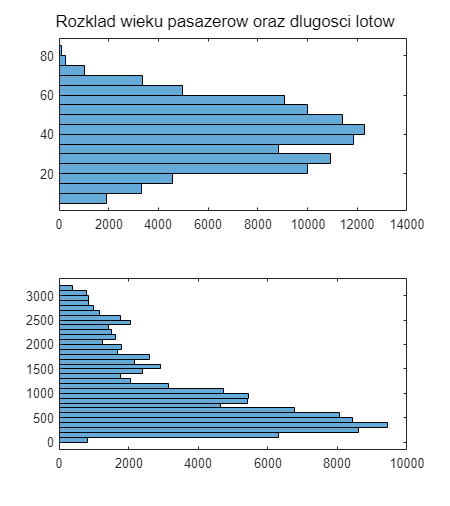

f0 = figure;
%zwiekszamy wysokosc rysunku
f0.Position = f0.Position .* [1,1,1,1.5];
subplot(2, 1, 1);
h01 = histogram(pasazerowie.Age,"BinWidth",5,"Orientation","horizontal");
subplot(2, 1, 2);
h02 = histogram(pasazerowie.FlightDistance, BinWidth=100, Orientation="horizontal");
sgtitle("Rozklad wieku pasazerow oraz dlugosci lotow");

### Wykres kołowy

Na tym znanym i lubianym typie wykresu przedstawiamy rozkład klas wybieranych przez badanych pasażerów.

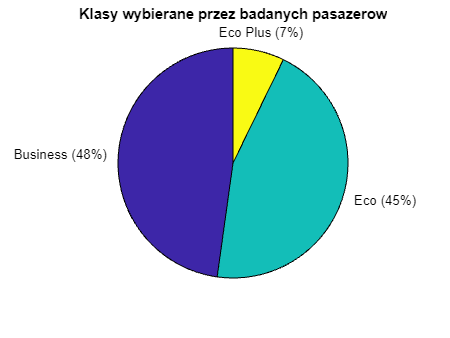

f1 = figure;
p2 = pie(pasazerowie.Class);
title('Klasy wybierane przez badanych pasazerow');

### Wykres pudełkowy i połączenie kategorii

Na wykresach pudełkowych przedstawiamy rozkład dwóch rodzajów średnich ocen w poszczególnych klasach przed i po połączeniu klas Eco i Eco Plus w jedną.

%categories(pasazerowie.Class)
f2 = figure;
%ustawiamy wysokosc rysunku na podwojna
f2.Position = f2.Position .* [1,1,1,2];
subplot(2, 2, 1);
boxplot(pasazerowie.FlightRating, pasazerowie.Class);
title('Obsluga lotu');
subplot(2, 2, 2);
boxplot(pasazerowie.GroundServiceRating, pasazerowie.Class);
title('Obsluga naziemna');

Łączymy kategorie klas "Eco" i "Eco Plus" w jedną kategorię "Eco" i tworzymy wykresy pudełkowe po połączeniu.

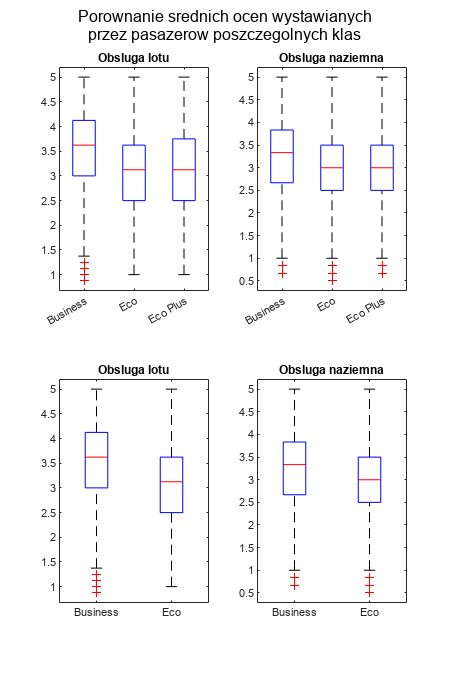

oldcats={'Eco','Eco Plus'};
pasazerowie.Class = mergecats(pasazerowie.Class, oldcats);
%categories(pasazerowie.Class)
subplot(2, 2, 3);
%hold on
boxplot(pasazerowie.FlightRating, pasazerowie.Class);
title('Obsluga lotu');
%hold off
subplot(2, 2, 4);
boxplot(pasazerowie.GroundServiceRating, pasazerowie.Class);
title('Obsluga naziemna');
sgtitle(["Porownanie srednich ocen wystawianych","przez pasazerow poszczegolnych klas"]);

### Wykres punktowy z histogramem

W ramach wykresu punktowego z histogramem przedstawiamy relację między obiema miarami agregującymi wystawiane przez pasażerów oceny oraz zarys częstości występowania poszczególnych wartości.

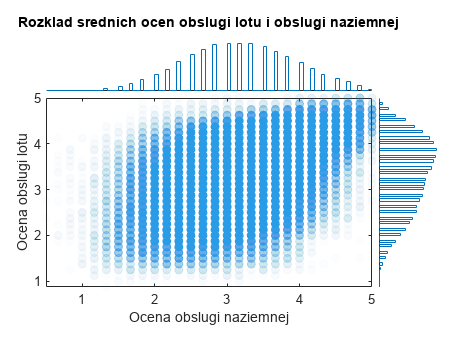

f3 = figure;
s3 = scatterhistogram(pasazerowie, "GroundServiceRating","FlightRating");
s3.MarkerFilled = "on"; %wypelnienie markerow
s3.MarkerAlpha = 0.01; %przezroczystosc markerow
s3.XLabel = "Ocena obslugi naziemnej";
s3.YLabel = "Ocena obslugi lotu";
s3.Title = "Rozklad srednich ocen obslugi lotu i obslugi naziemnej";

### Tabela z osią czasu

Tworzymy tabelę z osią czasu na bazie dotychczasowej tabeli.

pastt = table2timetable(pasazerowie);

Usuwamy wszystkie kolumny zawierające oceny, z których średnie wyznaczono wcześniej w nowych kolumnach i sortujemy dane chronologicznie, według godziny odlotu.

pastt = removevars(pastt, ["InflightWifiService", "Departure_ArrivalTimeConvenient", "EaseOfOnlineBooking","GateLocation","FoodAndDrink","OnlineBoarding","SeatComfort","InflightEntertainment","On_boardService","LegRoomService","BaggageHandling","CheckinService","InflightService","Cleanliness"]);
pastt = sortrows(pastt,"DepartureTime","ascend");

Zaokrąglamy wartości średnich ocen do 1. miejsca po przecinku.

pastt.FlightRating = round(pastt.FlightRating, 1);
pastt.GroundServiceRating = round(pastt.GroundServiceRating, 1);
pastt.GeneralRating = round(pastt.GeneralRating, 1);

### Wykres typu heatmap

Na heatmapie prezentujemy częstości występowania poszczególnych wartości obu średnich ocen w grupach pasażerów wyrażających ogólne zadowolenie z całokształtu usług linii lotniczych oraz tych wyrażających niezadowolenie (lub nastawionych neutralnie).

f4 = figure;
f4.Position = f4.Position .* [1,1,1,2.5];
subplot(2, 1, 1);
h1 = heatmap(pastt, "Satisfaction", "FlightRating",'XLabel', 'Ogolna ocena zadowolenia', 'YLabel', 'Ocena obslugi lotu');

W poniższych linijkach wykonujemy kolejne kroki zmierzające do zmiany wyświetlanych etykiet osi y, gdyż domyślnie wyświetlają się wszystkie wartości co 0.1, co powodowało zaciemnienie rysunku.

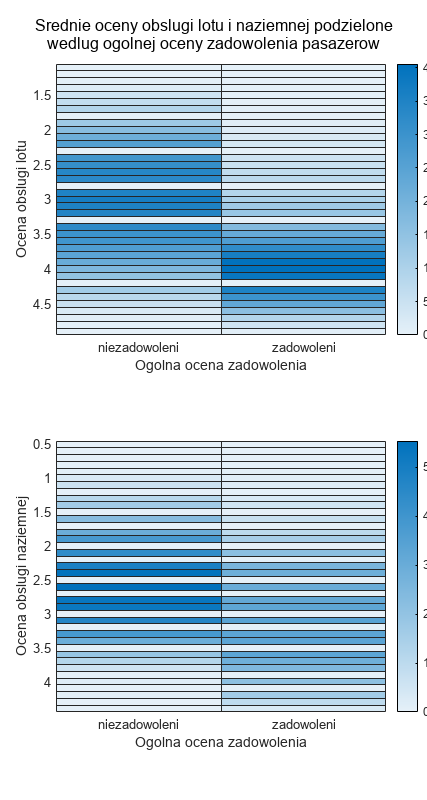

ylabh1 = 1:length(h1.YDisplayData);
ylabh1 = (ylabh1.*0.1)+1;
sylabh1 = string(ylabh1);
%wstawiamy spacje w miejsce co 5. etykiety, zeby uzyskac efekt wyswietlania
%wartosci co 0.5
sylabh1(mod(ylabh1*10, 5) ~= 0) = " ";
h1.YDisplayLabels = sylabh1;
%h1.Title = ["Srednie oceny obslugi lotu wsrod pasazerow","niezadowolonych (lub nastawionych neutralnie)","oraz zadowolonych"];
h1.Title = "";
h1.XDisplayLabels = ["niezadowoleni","zadowoleni"];

subplot(2, 1, 2);
h2 = heatmap(pastt, "Satisfaction", "GroundServiceRating",'XLabel', 'Ogolna ocena zadowolenia', 'YLabel', 'Ocena obslugi naziemnej');
ylabh2 = 1:length(h2.YDisplayData);
ylabh2 = (ylabh2.*0.1)+0.4;
sylabh2 = string(ylabh2);
sylabh2(mod(ylabh2*10, 5) ~= 0) = " ";
h2.YDisplayLabels = sylabh2;
%h2.Title = ["Srednie oceny obslugi naziemnej wsrod","pasazerow niezadowolonych (lub","nastawionych neutralnie) oraz zadowolonych"];
h2.Title = "";
h2.XDisplayLabels = ["niezadowoleni","zadowoleni"];
sgtitle(["Srednie oceny obslugi lotu i naziemnej podzielone","wedlug ogolnej oceny zadowolenia pasazerow"]);

### Normalizacja danych

Pomijając kilka niewykorzystanych w analizie kolumn, duża część zmiennych należy do danych kategorycznych, na których nie wykonujemy normalizacji. Za najistotniejsze zmienne można uznać te zawierające oceny wystawione przez pasażerów oraz wartości opóźnień w minutach. O ile oceny są spójnie wyrażone we wspólnej skali 0-5, tak opóźnienia mogą mieć dowolne wartości naturalne. Żeby umożliwić ewentualny proces grupowania między tymi rodzajami zmiennych, wykonujemy normalizację kolumn je opisujących.

M = [pastt.DepartureDelayInMinutes, pastt.ArrivalDelayInMinutes, pastt.FlightRating, pastt.GroundServiceRating, pastt.GeneralRating];
%normalizujemy dane w macierzy, bo odleglosci miedzy danymi w kolumnie
%Fuel_cost sa bardzo male w porownaniu do Sales i zaburzalyby proces
%grupowania, w ktorym dane blisko siebie sa laczone
M = normalize(M, "range");

Po wykonaniu normalizacji przedstawiamy na wykresie punktowym przykładowe znormalizowane dane (kolumny zawierające opóźnienie przylotu oraz średnie wszystkich ocen).

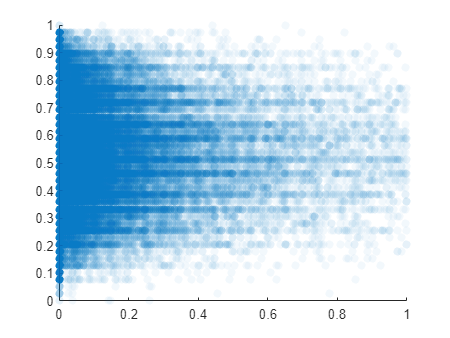

f6 = figure;
s4 = scatter(M(:,2), M(:,5),"filled","o",MarkerFaceAlpha=0.05,MarkerEdgeAlpha=0.05);

## Zapis danych

save('pastt.mat',"pastt");